# Create balanced football or rugby squares game board

`footballsquares(playernames)` creates a football squares game board for the participants given in the string array (or cell array of char vectors) `playernames`. The board is labeled with the defaul labels "Home Team" and "Away Team". `footballsquares(playernames,teamnames)` labels the board with the team names given in the two-element string array (or cell array of char vectors) `teamnames`.

## Options

- `Sport`: `"football"` (default) or `"rugby"`. Sets the probabilities, based on historical results.

- `Color`: Two-element string array (or cell array of chars) or 2-by-3 matrix of RGB values. The colors to use for the squares in the grid.

- `ProbWeight`: scalar in [0,1]. Deafult = 0.75. The weighting of equal probability vs. equal distribution of squares. 0 ignores probability and attempts to equalize distribution of squares to each player. 1 ignores the number and distribution of squares and attempts to ensure each player has equal probability of winning. Other values result in optimizing a weighted average of the two.

- `Method`: `"auto"` (default), `"montecarlo"`, or `"optim"`. Determines how the distribution of squares is calculated. `"montecarlo"` takes the best of many random distributions. `"optim"` uses GA optimization (if available - requires Global Optimization Toolbox). `"auto"` determines if GA is available and uses it if so, otherwise it uses Monte Carlo simulation.

- `NumExperiments`: scalar value. The number of experiments to run when performing Monte Carlo simulation. Ignored if `Method` is `"optim"`.

## Examples

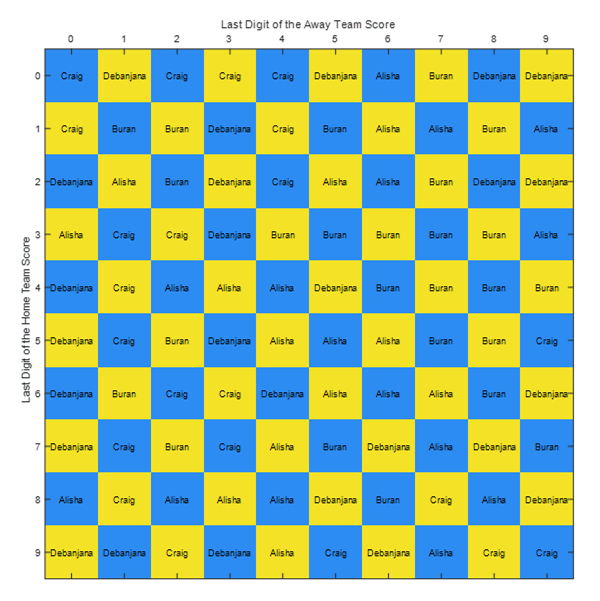

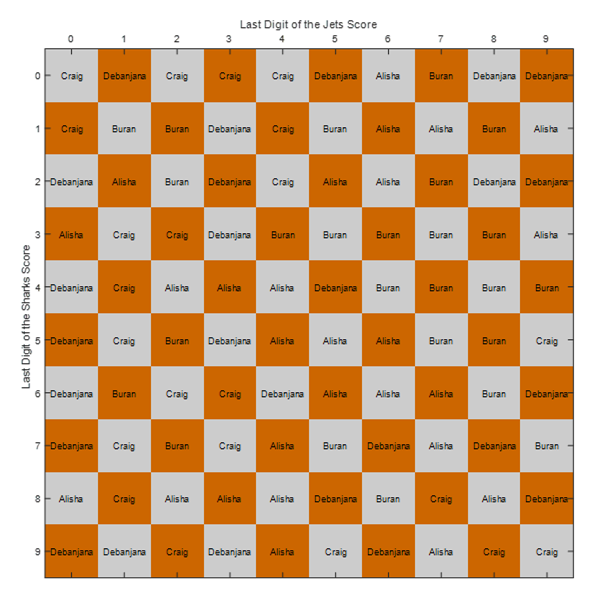

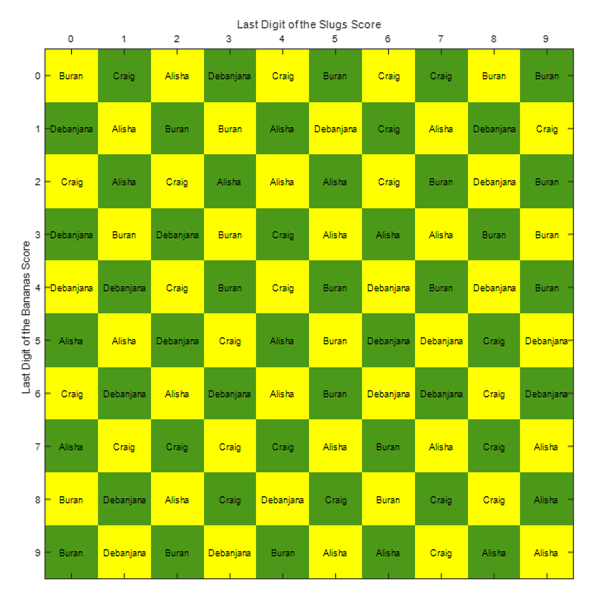

## About

#### The game

*Football Squares* is a simple game of chance that can be used to add interest to a football-watching social event. It requires no knowledge of football, so everyone can play. Each player is assigned a random selection of squares from a 10-by-10 grid (with every square taken by exactly one player). At specific points in the game (typically the end of each quarter), the score of the game is used to determine a winner by looking up the row and column of the grid corresponding to the last digits of the two teams' scores. For example, if the score is 21-17, then in the example below, Alisha -- having the "1-7" square -- is the winner:

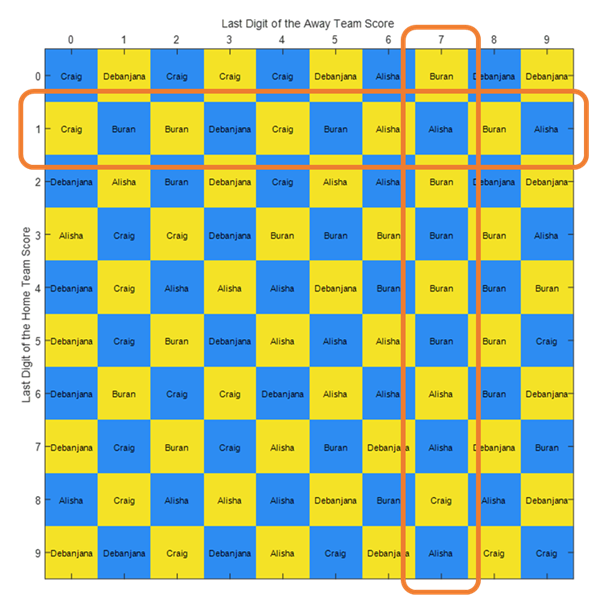

#### Extensions

The game can be applied equally well to any head-to-head sport where the last digit of the score can (realistically) change to any value with reasonably equal probability. Hence, rugby works well, but soccer does not.

#### Unequal Probabilities

Although all digits can and do occur in football, the probabilities are not equal. Hence, some squares are better than others. This means that one player could have a significantly greater chance of winning than another, even if all players are assigned an equal number of squares. For rugby, the same problem exists although the probabilities are more evenly distributed. Assigning squares, then, becomes a trade-off between equal distribution of squares and equal probability of winning.

Furthermore, even if probability is ignored, 10 players could have be assigned an equal number of squares by giving each player one whole row or column. This would mean that the result (of the football squares game) is entirely determined by only one team's score. In general, it is better to have players' squares as evenly distributed as possible across both rows and columns.

#### Algorithm

This implementation optimizes a combination of distribution and probability. For probability, the biggest difference in total probability (between players) is minimized. The probabilities of the individual squares are determined by historical results. For distribution, a penalty score is minimized, calculated from: the difference in total number of squares (between players); the range (for each player) between the number of squares in each column; and the range (for each player) between the number of squares in each row.

The weighting between probability and distribution is given by the `ProbWeight` parameter.

The assignment of the squares is done by minimizing the weighted score (probability & distribution). This optimization is an integer-programming problem with a nonlinear objective. It can be solved with GA or by brute-force random experimentation.

function footballsquares(playernames,teamnames,options)
arguments
    playernames string {checknames}
    teamnames (1,2) string = ["Home Team","Away Team"]
    options.Sport string {mustBeMember(options.Sport,["football","rugby"])} = "football"
    options.Method string {mustBeMember(options.Method,["auto","montecarlo","optim"])} = "auto"
    options.NumExperiments (1,1) double {mustBePositive} = 1e4
    options.Colors = [0.18 0.55 0.95;0.96 0.89 0.15]
    options.ProbWeight (1,1) double {mustBeNonnegative, mustBeLessThanOrEqual(options.ProbWeight,1)} = 0.75
end

playernames = convertCharsToStrings(playernames);
options.Colors = checkcolors(options.Colors);

canusga = false;
if (exist("ga","file") == 2)
    canusga = contains(which("ga"),"global");
end
if isequal(options.Method,"optim") && ~canusga
    warning("Optimization method is not available - using Monte Carlo instead")
    options.Method = "montecarlo";
end

if isequal(options.Method,"auto")
    if canusga
        options.Method = "optim";
    else
        options.Method = "montecarlo";
    end
end

% disp(playernames)
% disp(teamnames)
% disp(options)


Now the fun

nplayers = length(playernames);

Define the probabilities for each pair of digits. These were determined from previous scores (see `getprobabilities.mlx`). `p` is a vector of the unrolled vector of probabilities.

switch options.Sport
    case "football"
        p = [1.62857978740695;1.60582517959887;0.728147449858596;3.08812534538244;2.75005688651952;0.66313428469265;
            1.86587784026265;4.15109059584566;1.07596788349641;0.858173780190489;1.60582517959887;0.435588206611839;
            0.321815167571433;1.03370932613854;1.97640022104476;0.432337548353542;0.620875727334785;2.05766667750219;
            0.978448135747489;0.425836231836947;0.728147449858596;0.321815167571433;0.0195039495497838;0.390078990995677;
            0.523355979585866;0.191788837239541;0.256802002405487;0.640379676884569;0.188538178981244;0.240548711114001;
            3.08812534538244;1.03370932613854;0.390078990995677;0.650131651659461;1.6903422943146;0.435588206611839;
            1.38152975977635;2.39573513636511;0.620875727334785;0.611123752559893;2.75005688651952;1.97640022104476;
            0.523355979585866;1.6903422943146;0.991450768780678;0.598121119526704;1.06946656697981;3.57897474238533;
            1.03370932613854;0.630627702109677;0.66313428469265;0.432337548353542;0.191788837239541;0.435588206611839;
            0.598121119526704;0.0812664564574326;0.221044761564217;0.786659298507948;0.364073724929298;0.152780938139973;
            1.86587784026265;0.620875727334785;0.256802002405487;1.38152975977635;1.06946656697981;0.221044761564217;
            0.315313851054839;1.42053765887592;0.380327016220785;0.464844130936515;4.15109059584566;2.05766667750219;
            0.640379676884569;2.39573513636511;3.57897474238533;0.786659298507948;1.42053765887592;1.40103370932614;
            1.13447973214576;0.861424438448786;1.07596788349641;0.978448135747489;0.188538178981244;0.620875727334785;
            1.03370932613854;0.364073724929298;0.380327016220785;1.13447973214576;0.201540812014433;0.201540812014433;
            0.858173780190489;0.425836231836947;0.240548711114001;0.611123752559893;0.630627702109677;0.152780938139973;
            0.464844130936515;0.861424438448786;0.201540812014433;0.0780157981991353];
    case "rugby"
        p = [0.861538461538462;1.10769230769231;1.41538461538462;1.84615384615385;1.32307692307692;1.01538461538462;
            1.47692307692308;1.13846153846154;1.38461538461538;1.41538461538462;1.10769230769231;0.338461538461538;
            0.769230769230769;1.16923076923077;0.553846153846154;0.8;0.923076923076923;0.676923076923077;0.707692307692308;
            0.769230769230769;1.41538461538462;0.769230769230769;0.307692307692308;0.892307692307692;0.953846153846154;
            0.923076923076923;1.75384615384615;1.10769230769231;0.584615384615385;1.04615384615385;1.84615384615385;
            1.16923076923077;0.892307692307692;0.707692307692308;1.2;1.01538461538462;1.32307692307692;1.35384615384615;
            1.10769230769231;1.56923076923077;1.32307692307692;0.553846153846154;0.953846153846154;1.2;0.369230769230769;
            0.8;0.923076923076923;0.861538461538462;0.8;0.953846153846154;1.01538461538462;0.8;0.923076923076923;
            1.01538461538462;0.8;0.4;1.2;1.23076923076923;0.646153846153846;1.07692307692308;1.47692307692308;
            0.923076923076923;1.75384615384615;1.32307692307692;0.923076923076923;1.2;0.830769230769231;0.953846153846154;
            0.553846153846154;1.29230769230769;1.13846153846154;0.676923076923077;1.10769230769231;1.35384615384615;
            0.861538461538462;1.23076923076923;0.953846153846154;0.553846153846154;0.707692307692308;0.769230769230769;
            1.38461538461538;0.707692307692308;0.584615384615385;1.10769230769231;0.8;0.646153846153846;0.553846153846154;
            0.707692307692308;0.553846153846154;1.2;1.41538461538462;0.769230769230769;1.04615384615385;1.56923076923077;
            0.953846153846154;1.07692307692308;1.29230769230769;0.769230769230769;1.2;0.492307692307692];
end

Define the objective to minimize: a combination of the difference in total probability (among all the players), how concentrated on any one score any given player is, and how many squares any given player has. (Adjust the `probweight` parameter to weight the various factors against each other.)

if (options.ProbWeight == 0)
    objf = @(x) distpenalty(x,nplayers);
elseif (options.ProbWeight == 1)
    objf = @(x) mintomax(prob(x,p,nplayers));
else
    objf = @(x) options.ProbWeight*mintomax(prob(x,p,nplayers)) + (1-options.ProbWeight)*distpenalty(x,nplayers);%(max(mixpenalty(x,nplayers),[],1) + numpenalty(x,nplayers));
end


Find the optimal solution, using the chosen method.

switch options.Method
    case "montecarlo"
        bestf = Inf;
        for k = 1:options.NumExperiments
            idx = randi(nplayers,1,100);
            f = objf(idx);
            if f < bestf
                bestidx = idx;
                bestf = f;
            end
        end
        idx = bestidx;
    case "optim"
        idx = ga(objf,100,[],[],[],[],ones(100,1),nplayers*ones(100,1),[],1:100,...
            optimoptions("ga","UseVectorized",true,"MaxStallGenerations",500,...
            "PopulationSize",400,"MaxGenerations",5000,"Display","none"));
end

names = playernames(idx);
drawsquares(names,options.Colors,teamnames)
end

function drawsquares(names,colors,teams)
% Use the clever inverse Hilbert trick to get a checkerboard
a = invhilb(10)<0;
% Draw the checkerboard matrix
tick = 0:9;
imagesc(tick,tick,a)
colormap(colors)
set(gca,"FontSize",12,"XAxisLocation","top","XTick",tick,"YTick",tick)
axis square
xlabel("Last Digit of the "+teams(2)+" Score")
ylabel("Last Digit of the "+teams(1)+" Score")
% Add players' names
[row,col] = ind2sub([10,10],1:100);
text(col-1,row-1,names,"FontSize",10,"Color","k","HorizontalAlignment","center");
end

function r = prob(idx,p,nplayers)
% Calculate the total probability for each player
% idx is nexp-by-100 -- each row is an assignment of the 100 squares to
% the players (by number)
nexp = size(idx,1);
r = zeros(nplayers,nexp);
for k = 1:nexp
    % extract each row and use the player number to accumulate the
    % probabilities
    r(:,k) = accumarray(idx(k,:)',p,[nplayers 1],[],0);
end
end

function pen = distpenalty(idx,nplayers)
% Calculate the penalty for having uneven distribution of squares for
% a particular player
nexp = size(idx,1);
% penmix = zeros(nplayers,nexp);
pen = zeros(1,nexp);
for k = 1:nexp
    % Count the squares assigned to each player and take the minimum
    n = accumarray(idx(k,:)',1,[nplayers 1],[],0);
    ncap = min(n,10);
    % Look at how many squares each player has in each row and column
    % Calculate the difference (max - min) for both rows and columns
    pfun = @(player) mintomax(sum(reshape(idx(k,:),10,10)==player));
    byrows = arrayfun(pfun,1:nplayers)'./ncap;
    pfun = @(player) mintomax(sum(reshape(idx(k,:),10,10)==player,2));
    bycols = arrayfun(pfun,1:nplayers)'./ncap;
    %     penmix(:,k) = arrayfun(pfun,1:nplayers)';
    pen(k) = (1 - min(n)/max(n)) + max(byrows) + max(bycols);
end
end

function y = mintomax(x)
y = max(x) - min(x);
end

function checknames(playernames)
playernames = convertCharsToStrings(playernames);
if ~(isvector(playernames) && isstring(playernames))
    error("Player names should be a vector of text (string or cellstr)")
end
if isscalar(playernames)
    error("Only one player!")
end
end

function cnum = checkcolors(c)
c = convertCharsToStrings(c);
if isstring(c) && (numel(c)==2)
    cnum = zeros(2,3);
    for k = 1:2
        switch c(k)
            case {"r","red"}
                cnum(k,:) = [1 0 0];
            case {"g","green"}
                cnum(k,:) = [0 1 0];
            case {"b","blue"}
                cnum(k,:) = [0 0 1];
            case {"y","yellow"}
                cnum(k,:) = [1 1 0];
            case {"m","magenta"}
                cnum(k,:) = [1 0 1];
            case {"c","cyan"}
                cnum(k,:) = [0 1 1];
            case {"w","white"}
                cnum(k,:) = [1 1 1];
            case {"k","black"}
                cnum(k,:) = [0 0 0];
        end
    end
else
    cnum = c;
end
if ~(isnumeric(cnum) && isequal(size(cnum),[2 3]))
    error("Team colors should be specified as text or a 2-by-3 RGB matrix")
end
end